# Linear Regression

clc; % clean command propmt
clear; % clean exist varaibles
close all; % close all figures.

### Load data

The built-in dataset named "carsmall" are used in this practice

This data contains the specification for 100 different models of cars

data = importdata("carsmall.mat");

### Define independent variable (IV) and dependent variable (DV)

**IV** - Pick the feature(type of spec) that you want to use to predict the Y

**DV** - Predict Mile per gallon(MPG) using other specs

% Choose the independent variable (IV) of interest
IV{1} = data.Displacement;
IV{2} = data.Weight;
IV{3} = data.Model_Year;

% Do not change the dependent variable
DV = data.MPG;

### 선형 회귀 모델 (lm) 피팅하기

% 각 IVs 마다 lm 훈련하기
clear lm beta pval
for i = 1: length(IV)
    lm{i} = fitlm(IV{i}, DV);
    beta(i,:) = lm{i}.Coefficients.Estimate;
    pval(i) = lm{i}.Coefficients.pValue(2);
end

fitting된 linear model에 대한 다른 coefficients에 대한 값은 명령어 프롬프트에 "doc filtlm"을 실행시켜보세요.

plot the fitted linear function for each variable

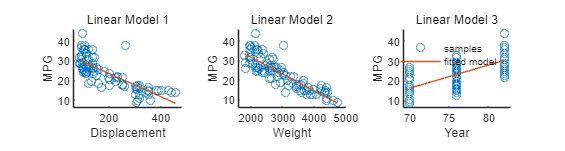

% regress MPG on Acceleration
xlabelnames = {'Displacement' 'Weight' 'Year'};
figure('Position',[100 100 1200 320]);
tiledlayout(1,3)
for i = 1: length(lm)
    IV_range = linspace( min(IV{i}), max(IV{i}), 100 );
    DV_hat = beta(i,1) + IV_range.*beta(i,2); % estimate DVs.

    nexttile();
    sc(i) = scatter(IV{i}, DV, 'Color','b', 'Marker','o'); hold on;
    plt(i) = plot(IV_range, DV_hat);

    % figure options
    xlabel(xlabelnames{i}); ylabel('MPG');
    title(['Linear Model ' num2str(i)])
    xlim('padded'); ylim('padded')
end
legend([sc(end), plt(end)], {'samples', 'fitted model'},'box','off')

% Compare the fitness using mean square error
rmse = nan(size(lm));
rsqr = nan(size(lm));
for i = 1: length(lm)
    rmse(i) = lm{i}.RMSE; 
    rsqr(i) = lm{i}.Rsquared.Ordinary;
end

plot

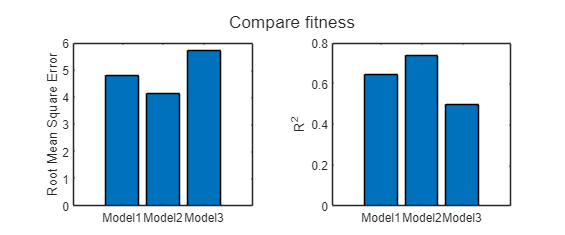

label = {'Model1','Model2','Model3'};

figure('Position',[100 100 720 300]);
% Plot the root mean square error of each model
nexttile();
bar(1:3, rmse)
xticklabels(label)
ylabel('Root Mean Square Error')

% Plot the R squared of each model
nexttile();
bar(1:3,rsqr)
xticklabels(label)
ylabel('R^{2}')
sgtitle('Compare fitness')

## Multi-linear regression

Pick the feature(type of spec) that you want to use to predict the Y

% Predict Mile per gallon(MPG) using other specs
IVs = [data.Acceleration data.Weight data.Cylinders];
DV = data.MPG;

% Remove NaN in the sample
idx_mask = isnan(DV);
IVs(idx_mask,:) = [];
DV(idx_mask,:) = [];

using function

% Linear regression function
mlm = fitlm(IVs, DV);

% Compare the fitness using mean square error
rmse_full = mlm.RMSE; 
rsqr_full = mlm.Rsquared.Ordinary;

Linear regression using least square method

% Our linear model is as follow
% y = b0 + b1*x1 + b2*x2 + b3*x3
X = [ones(size(IVs,1),1), IVs];
b = inv(X'*X)*X'*DV;

Compare the coefficient from two different method

name = {'b0';'b1';'b2';'b3'};
method1 = mlm.Coefficients.Estimate;
method2 = b;
table(name,method1,method2)

ans = 4×3 table
     name      method1       method2  
    ______    __________    __________

    {'b0'}        49.378        49.378
    {'b1'}     -0.023114     -0.023114
    {'b2'}    -0.0056194    -0.0056194
    {'b3'}       -1.5708       -1.5708


### Compare the fitness of full model to simple linear regression model

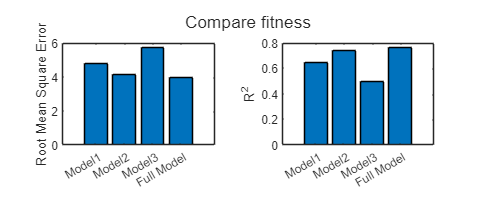

label = {'Model1','Model2','Model3','Full Model'};

figure('Position',[100 100 480 200]);
% Plot the root mean square error of each model
nexttile();
bar(1:4,[rmse, rmse_full])
xticklabels(label)
ylabel('Root Mean Square Error')

% Plot the R squared of each model
nexttile();
bar(1:4,[rsqr rsqr_full])
xticklabels(label)
ylabel('R^{2}')

sgtitle('Compare fitness')